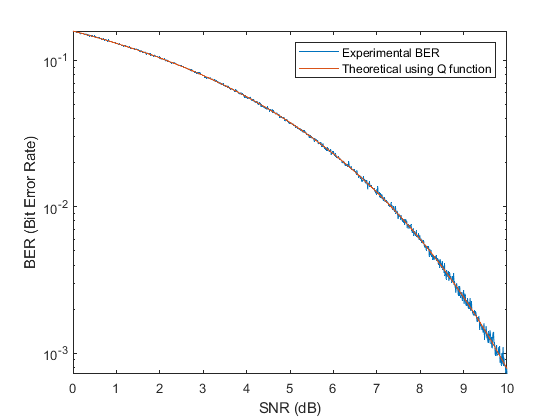

%Demonstration BPSK modulation and Demodulation with AWGN with
%unit mean and SNR's varrying from 0-10 dB .

%We take the input signal as -1 everytime to make implementation a little
%faster. We then add the AWGN with unit mean and compare it with -1 if its
%closer to 1 we have a bit error and count all such errors for all values of
%SNR. We have taken 10^5 and 10^6 bits of signal in this experiment.
%We have not used any modules to hope for faster implementation of code.

clc;
clear all;
close all;

%generate BPSK constellation as complex numbers
a=[zeros(1,1);ones(1,1)];
constellation = exp(1i*2*pi.*a/2);

%number of symbols in simulation
nsymbols = 100000; %Change it to 10,00,000 > represents number of symbols used for stimulation.
snr = 0:0.01:10; %We change SNR from 1-10 dB.

%We assume the input signal to be -1 for all symbols.
number_snrs = length(snr); %Number of snr values to check
perr_estimate = zeros(number_snrs,1); %To estimate error for each SNR value and add it to estimate

for k=1:number_snrs %SNR for loop
    snr_now = snr(k); %The current value of snr being tested for BER.
    ebno=10^(snr_now/10); %We convert snr from dB to decimal unit.
    sigma=sqrt(1/(ebno)); %The corresponding varience for noise.
    % add 2d Gaussian noise to our symbols.
    received = -1 + sigma*randn(nsymbols,1)+1i*sigma*randn(nsymbols,1); % To add complex WBGN noise to our input signal -1.
    decisions=zeros(nsymbols,1); %We initialize decisions with zeros corresponding to all n symbols.
    for n=1:nsymbols %Symbol for loop to compute distance which is used to stimulate recieved signal being 1 or -1.
        distances = abs(received(n)-constellation); %It stores a vector of absolute distance 
                                                        %from each of the constellation points 1 and -1.
        [min_dist,decisions(n)] = min(distances); %We store the minimum of those distances with memory location 
                                                   %(which will be 1 if the point is closer to the constellation point1
                                                   %and 2 if the point is closer to the constellation point -1.)
    end
    for n=1:nsymbols   %We know that value of 2 is decisions correspond to recieved signal being -1 so we replace that with -1.
                         %Which mean no error occured for this bit due to AWGN.
       if decisions(n)~=1
           decisions(n)=-1;  %This will replace all non 1 values with -1 , since its BPSK we can only have 1 or -1 as symbols.
       end
    end
    errors = (decisions ~= -1); %All non -1 results are errors (as our recieved signal is 1 different from input signal of -1)
                                 %and stored in errors.
    
    perr_estimate(k) = sum(errors)/nsymbols; %This gives BER per symbol.
end
semilogy(snr,perr_estimate); %To plot the BER per nsymbols with SNR.
hold on; %To add both data in the same plot
semilogy(snr,qfunc(sqrt(10.^(snr/10)))); % To plot BER theoretical using Q-function .
legend("Experimental BER ","Theoretical using Q function"); %To all legend
xlabel("SNR (dB)"); %To add SNR label to x axis
ylabel("BER (Bit Error Rate)"); %To add BER label to y axis. its BER per symbol.